try
    pyenv('Version','C:/Users/tkaneko/anaconda3/envs/openmmlab/python.exe');
catch
end

dtbl=readtable('./labeledGT/valbin3_nanim3_nfrm35/framedata.csv','ReadRowNames',1,'NumHeaderLines',1);
head(dtbl)

                                            Var1                            Var2    Var3    Var4    Var5    Var6    Var7    Var8    Var9
                     ___________________________________________________    ____    ____    ____    ____    ____    ____    ____    ____

    mov1_00033708    {'dl_chd82_ctrl_cj282cj719_cj883m_20221115_150000'}     809     810     810     809     810     809     810     809
    mov1_00142041    {'dl_chd82_ctrl_cj282cj719_cj883m_20221115_150000'}    3409    3409    3409    3409    3409    3409    3409    3409
    mov1_00202458    {'dl_chd82_ctrl_cj282cj719_cj883m_20221115_150000'}    4859    4859    4859    4859    4859    4859    4859    4859
    mov1_00229541    {'dl_chd82_ctrl_cj282cj719_cj883m_20221115_150000'}    5510    5510    5510    5509    5510    5510    5510    5509
    mov1_00250375    {'dl_chd82_ctrl_cj282cj719_cj883m_20221115_150000'}    6009    6009    6009    6009    6009    6009    6009    6009
    mov1_00303500    {'dl_chd82_ctrl_cj2

% summary(dtbl)

sessions=unique(dtbl.Var1);

clear annotKp3ds
clear decodedKp3ds
cnt=0;
for ises=1:length(sessions)
    session=sessions{ises};
    flgses=strcmp(dtbl.Var1,session);
    currdtbl=dtbl(flgses,:);



    dirPickleRoot='data';
    picklefile=sprintf('%s/%s/kp3d_fxdJointLen.pickle',dirPickleRoot,session);
    if ~exist(picklefile)
    dirPickleRoot2='Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark_fam3anims';
    picklefile2=sprintf('%s/%s/kp3d.pickle',dirPickleRoot2,session);
        mkdir(sprintf('%s/%s',dirPickleRoot,session));
        copyfile(picklefile2,picklefile)        
    end 


    fid=py.open(picklefile,'rb');
    data=py.pickle.load(fid);
    data=struct(data);
    kp3d=double(data.kp3d);



    for ifrm=1:height(currdtbl);

        currfrm=round(mean(cell2mat(table2cell(currdtbl(ifrm,2:end)))));
        currfrm=currfrm-24*5;
        if currfrm<1 || currfrm>size(kp3d,2)
        continue
        end 
        cnt=cnt+1;
        frmName=currdtbl(ifrm,:).Row;

        jsondata=readjson(sprintf('./labeledGT/valbin3_nanim3_nfrm35/%s.json',frmName{1}));

        % switch subject
        cmbptr=[1,2,3,1,2,3;...
                1,2,3,1,3,2;...
                1,2,3,2,1,3;...
                1,2,3,2,3,1;...
                1,2,3,3,1,2;...
                1,2,3,3,2,1;];
        for irep=1:6
            annotKp3ds_=cat(3,squeeze(jsondata.keypoints_3d(cmbptr(irep,1),1:18,:)),...
                              squeeze(jsondata.keypoints_3d(cmbptr(irep,2),1:18,:)),...
                               squeeze(jsondata.keypoints_3d(cmbptr(irep,3),1:18,:)));
            currKp3ds_=cat(3,squeeze(kp3d(cmbptr(irep,4),currfrm,:,:)),...
                            squeeze(kp3d(cmbptr(irep,5),currfrm,:,:)),...
                            squeeze(kp3d(cmbptr(irep,6),currfrm,:,:)));
            tmpvals(irep)=mean(nanmedian(vecnorm((annotKp3ds_-currKp3ds_),2,2)));
        end
        % get subject
        [val,ind]=min(tmpvals);
        irep=ind;
        annotKp3ds(:,:,:,cnt)=cat(3,squeeze(jsondata.keypoints_3d(cmbptr(irep,1),1:18,:)),...
                                    squeeze(jsondata.keypoints_3d(cmbptr(irep,2),1:18,:)),...
                                    squeeze(jsondata.keypoints_3d(cmbptr(irep,3),1:18,:)));
        decodedKp3ds(:,:,:,cnt)=cat(3,squeeze(kp3d(cmbptr(irep,4),currfrm,:,:)),...
                                      squeeze(kp3d(cmbptr(irep,5),currfrm,:,:)),...
                                      squeeze(kp3d(cmbptr(irep,6),currfrm,:,:)));
        minval(cnt)=val;
    end
end

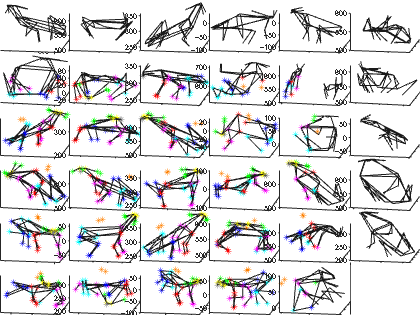

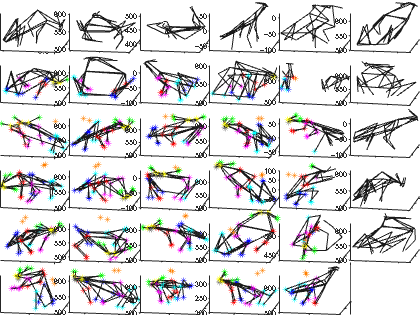

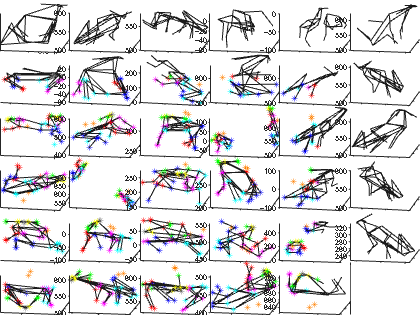

for ianim=1:3
    hfig=figure;
    haxs=subplot(1,1,1);hold on;
    haxss=tight_subplot(6,6,0,0,0);        
    for ifrm=1:35        
        annotKp3d=squeeze(annotKp3ds(:,:,ianim,ifrm));
        currKp3d=squeeze(decodedKp3ds(:,:,ianim,ifrm));
        haxs=haxss(ifrm);
        axes(haxs);
        hold on;
        [hplts, hplt_skpt] = plotMarmo3D(annotKp3d, haxs);
        [hplts, hplt_skpt] = plotMarmo3D(currKp3d, haxs);
        view([10 20]);
    end
end

gapdata=vecnorm((annotKp3ds-decodedKp3ds),2,2);
gapdata=nanmean(gapdata,2);

save('ThreeAnimals.mat','annotKp3ds','decodedKp3ds','minval');